**Interpolation:**  This file contains the code for Interpolating the existing Dataset. The various Datsets are interpolated and Smoothened as per requirement and minimal error.

clear;
clc;
close all;

%Population Interpolation.
%The datasets are loaded as arrays.

%Years.
%1950-2022.
Y=1:12:876;

%Population Dataset from 1950-2022 years.
Warangal=[130000 134000	136000	138000	140000	143000	145000	147000	150000	152000	154000	158000	162000	167000	172000	176000	181000	187000	192000	198000	203000	210000	220000	231000	243000	255000	267000	281000	295000	309000	325000	339000	350000	362000	375000	387000	400000	414000	428000	442000	457000	471000	481000	492000	502000	513000	524000	536000	547000	559000	571000	584000	600000	616000	632000	649000	666000	684000	702000	721000	740000	760000	780000	801000	822000	844000	867000	890000	914000	937000	960000	983000	1007000];
Nizamabad=[53000	56000	58000	60000	62000	65000	67000	69000	72000	74000	77000	80000	83000	86000	90000	93000	97000	100000	104000	108000	112000	117000	123000	128000	134000	141000	147000	154000	162000	169000	178000	185000	190000	195000	201000	206000	212000	218000	224000	230000	237000	242000	247000	251000	256000	261000	265000	270000	275000	280000	285000	289000	292000	294000	296000	298000	300000	303000	305000	307000	310000	312000	314000	317000	319000	321000	324000	326000	329000	331000	333000	337000	341000];
Khammam=[28000	28000	29000	30000	31000	31000	32000	33000	34000	34000	35000	36000	38000	40000	42000	44000	46000	48000	50000	53000	55000	58000	61000	64000	68000	72000	76000	81000	85000	90000	95000	100000	104000	109000	113000	118000	123000	128000	134000	139000	145000	151000	155000	159000	164000	169000	174000	179000	184000	189000	195000	200000	206000	212000	218000	224000	230000	237000	244000	250000	257000	265000	272000	280000	288000	296000	304000	313000	322000	330000	339000	347000	356000];
Karimnagar=[23000	24000	25000	25000	26000	27000	28000	28000	29000	30000	31000	32000	33000	35000	36000	38000	40000	42000	43000	45000	47000	50000	53000	56000	59000	62000	66000	70000	74000	78000	83000	88000	93000	98000	103000	109000	115000	122000	128000	136000	143000	151000	156000	163000	169000	176000	182000	190000	197000	205000	213000	221000	228000	235000	242000	250000	257000	266000	274000	283000	291000	301000	310000	320000	330000	340000	351000	362000	373000	384000	395000	406000	418000];

%Months.
%73 years from 1950-2022.
% 73 x 12 = 876 Months.
M=1:876;

%Interpolation.
%The Yearly dataset is interpolated to obtain Monthly Dataset. Linear
%Interpolation with Extrapolation is used as it is more natural.
Warangal_interpolated= interp1(Y,Warangal,M,'linear','extrap');
Nizamabad_interpolated= interp1(Y,Nizamabad,M,'linear','extrap');
Khammam_interpolated= interp1(Y,Khammam,M,'linear','extrap');
Karimnagar_interpolated= interp1(Y,Karimnagar,M,'linear','extrap');

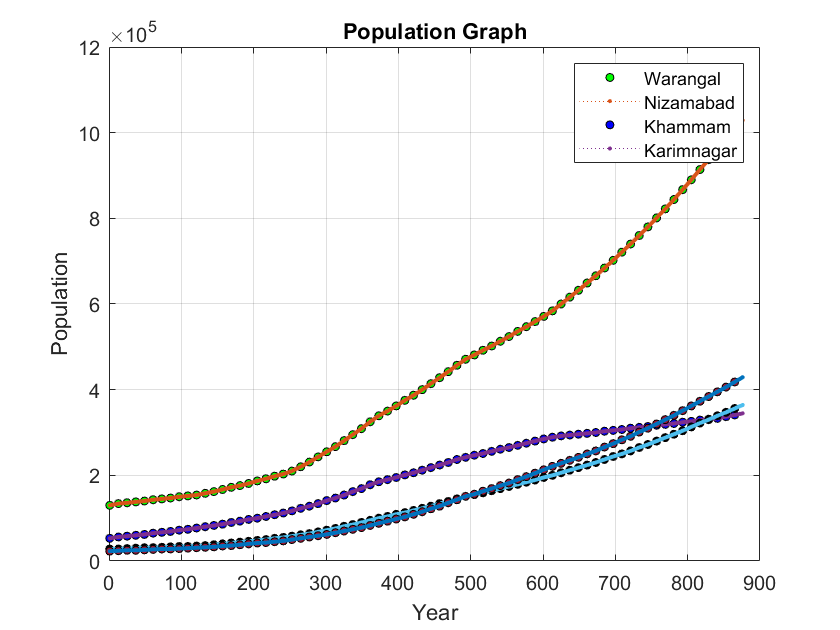

%Plotting the graphs.
h=plot(Y,Warangal,'go');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Warangal_interpolated,':.');
hold on;
h=plot(Y,Nizamabad,'bo');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Nizamabad_interpolated,':.');
hold on;
h=plot(Y,Khammam,'ko');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Khammam_interpolated,':.');
hold on;
h=plot(Y,Karimnagar,'o');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Karimnagar_interpolated,':.');
hold off;
grid on;
title('Population Graph');
xlabel('Year');
ylabel('Population');
legend('Warangal','Nizamabad','Khammam','Karimnagar');


%Saving the population data in a single vector.
Population_Monthly_Interpolated_Vector=[Warangal_interpolated Nizamabad_interpolated Khammam_interpolated Karimnagar_interpolated];

%Saving as .mat file.
save('Population_Monthly_Interpolated_Vector.mat','Population_Monthly_Interpolated_Vector');

clear;
clc;

%Energy Calculation.
%The TS NPDCL Energy Consumption Datasets are used.

%Path Directory.
%Contains the files from Jan 2019- Jan 2022.
%Contains 48 files.
files = dir('Energy\TS-NPDCL_consumption_detail_industrial_*.csv');
directory='Energy\';

%Empty Arrays to store Mean, Variance and Skewness of TotServices,
%BilledServices, Units and Load respectively.
% 3 Features from each value.
% 4 x 3 = 12 Features in total.
Energy_Warangal=[];
Energy_Nizamabad=[];
Energy_Khammam=[];
Energy_Karimnagar=[];

%Loading all the .csv files.
%There are 48 files, each corresponding to a month from 2019-2022.
for i=1:length(files)
    file_name = files(i).name;
    myMatrix = readtable([directory file_name]);
    
    %Loading all the values from Warangal Circle.
    myTable = find(strcmp(myMatrix.Circle,'WARANGAL'));
    Energy_Warangal_temp= [myMatrix.TotServices(myTable) myMatrix.BilledServices(myTable) myMatrix.Units(myTable) myMatrix.Load(myTable)]; 
    
    %Loading all the values from Nizamabad Circle.
    myTable = find(strcmp(myMatrix.Circle,'NIZAMABAD'));
    Energy_Nizamabad_temp= [myMatrix.TotServices(myTable) myMatrix.BilledServices(myTable) myMatrix.Units(myTable) myMatrix.Load(myTable)]; 
    
    %Loading all the values from Khammam Circle.
    myTable = find(strcmp(myMatrix.Circle,'KHAMMAM'));
    Energy_Khammam_temp= [myMatrix.TotServices(myTable) myMatrix.BilledServices(myTable) myMatrix.Units(myTable) myMatrix.Load(myTable)]; 
    
    %Loading all the values from Karimnagar Circle.
    myTable = find(strcmp(myMatrix.Circle,'KARIMNAGAR'));
    Energy_Karimnagar_temp= [myMatrix.TotServices(myTable) myMatrix.BilledServices(myTable) myMatrix.Units(myTable) myMatrix.Load(myTable)];
    
    %Calculating the mean, variance and skewness.
    Energy_Warangal=[Energy_Warangal; mean(Energy_Warangal_temp,1) var(Energy_Warangal_temp,1) skewness(Energy_Warangal_temp,1)];
    Energy_Nizamabad=[Energy_Nizamabad; mean(Energy_Nizamabad_temp,1) var(Energy_Nizamabad_temp,1) skewness(Energy_Nizamabad_temp,1)];
    Energy_Khammam=[Energy_Khammam; mean(Energy_Khammam_temp,1) var(Energy_Khammam_temp,1) skewness(Energy_Khammam_temp,1)];
    Energy_Karimnagar=[Energy_Karimnagar; mean(Energy_Karimnagar_temp,1) var(Energy_Karimnagar_temp,1) skewness(Energy_Karimnagar_temp,1)];
end

%Rearranging the values according to months.
%The files are read Apr, Aug, Dec, Feb, Jan, Jul, Jun, Mar, May, Nov, Oct,
%Sept order.
Energy_Warangal_temp=Energy_Warangal;
Energy_Warangal(1:4,:)=Energy_Warangal_temp(17:20,:);
Energy_Warangal(5:8,:)=Energy_Warangal_temp(13:16,:);
Energy_Warangal(9:12,:)=Energy_Warangal_temp(29:32,:);
Energy_Warangal(13:16,:)=Energy_Warangal_temp(1:4,:);
Energy_Warangal(17:20,:)=Energy_Warangal_temp(33:36,:);
Energy_Warangal(21:24,:)=Energy_Warangal_temp(25:28,:);
Energy_Warangal(25:28,:)=Energy_Warangal_temp(21:24,:);
Energy_Warangal(29:32,:)=Energy_Warangal_temp(5:8,:);
Energy_Warangal(33:36,:)=Energy_Warangal_temp(45:48,:);
Energy_Warangal(37:40,:)=Energy_Warangal_temp(41:44,:);
Energy_Warangal(41:44,:)=Energy_Warangal_temp(37:40,:);
Energy_Warangal(45:48,:)=Energy_Warangal_temp(9:12,:);

Energy_Nizamabad_temp=Energy_Nizamabad;
Energy_Nizamabad(1:4,:)=Energy_Nizamabad_temp(17:20,:);
Energy_Nizamabad(5:8,:)=Energy_Nizamabad_temp(13:16,:);
Energy_Nizamabad(9:12,:)=Energy_Nizamabad_temp(29:32,:);
Energy_Nizamabad(13:16,:)=Energy_Nizamabad_temp(1:4,:);
Energy_Nizamabad(17:20,:)=Energy_Nizamabad_temp(33:36,:);
Energy_Nizamabad(21:24,:)=Energy_Nizamabad_temp(25:28,:);
Energy_Nizamabad(25:28,:)=Energy_Nizamabad_temp(21:24,:);
Energy_Nizamabad(29:32,:)=Energy_Nizamabad_temp(5:8,:);
Energy_Nizamabad(33:36,:)=Energy_Nizamabad_temp(45:48,:);
Energy_Nizamabad(37:40,:)=Energy_Nizamabad_temp(41:44,:);
Energy_Nizamabad(41:44,:)=Energy_Nizamabad_temp(37:40,:);
Energy_Nizamabad(45:48,:)=Energy_Nizamabad_temp(9:12,:);

Energy_Khammam_temp=Energy_Khammam;
Energy_Khammam(1:4,:)=Energy_Khammam_temp(17:20,:);
Energy_Khammam(5:8,:)=Energy_Khammam_temp(13:16,:);
Energy_Khammam(9:12,:)=Energy_Khammam_temp(29:32,:);
Energy_Khammam(13:16,:)=Energy_Khammam_temp(1:4,:);
Energy_Khammam(17:20,:)=Energy_Khammam_temp(33:36,:);
Energy_Khammam(21:24,:)=Energy_Khammam_temp(25:28,:);
Energy_Khammam(25:28,:)=Energy_Khammam_temp(21:24,:);
Energy_Khammam(29:32,:)=Energy_Khammam_temp(5:8,:);
Energy_Khammam(33:36,:)=Energy_Khammam_temp(45:48,:);
Energy_Khammam(37:40,:)=Energy_Khammam_temp(41:44,:);
Energy_Khammam(41:44,:)=Energy_Khammam_temp(37:40,:);
Energy_Khammam(45:48,:)=Energy_Khammam_temp(9:12,:);

Energy_Karimnagar_temp=Energy_Karimnagar;
Energy_Karimnagar(1:4,:)=Energy_Karimnagar_temp(17:20,:);
Energy_Karimnagar(5:8,:)=Energy_Karimnagar_temp(13:16,:);
Energy_Karimnagar(9:12,:)=Energy_Karimnagar_temp(29:32,:);
Energy_Karimnagar(13:16,:)=Energy_Karimnagar_temp(1:4,:);
Energy_Karimnagar(17:20,:)=Energy_Karimnagar_temp(33:36,:);
Energy_Karimnagar(21:24,:)=Energy_Karimnagar_temp(25:28,:);
Energy_Karimnagar(25:28,:)=Energy_Karimnagar_temp(21:24,:);
Energy_Karimnagar(29:32,:)=Energy_Karimnagar_temp(5:8,:);
Energy_Karimnagar(33:36,:)=Energy_Karimnagar_temp(45:48,:);
Energy_Karimnagar(37:40,:)=Energy_Karimnagar_temp(41:44,:);
Energy_Karimnagar(41:44,:)=Energy_Karimnagar_temp(37:40,:);
Energy_Karimnagar(45:48,:)=Energy_Karimnagar_temp(9:12,:);

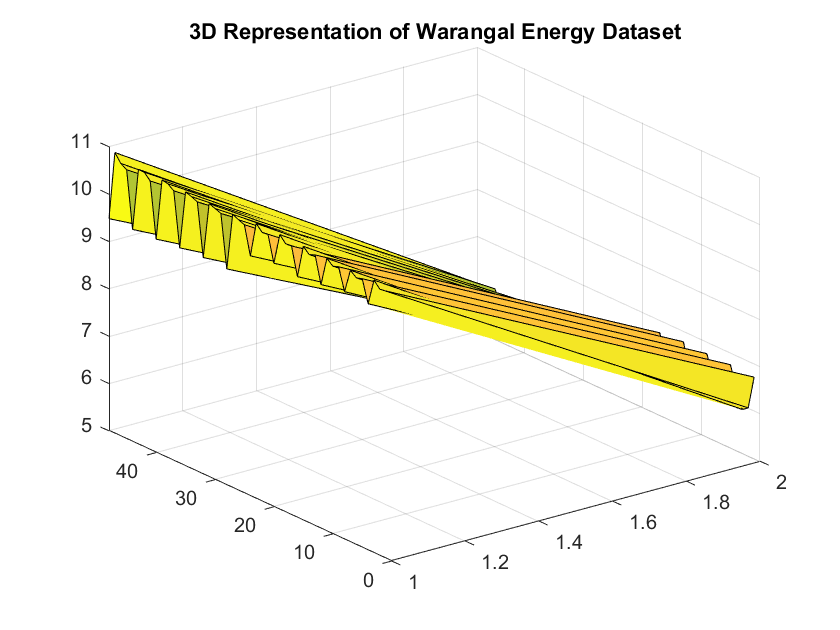

%Plotting to see various distributions of the Data.
%Looking at the non-linear nature of the dataset.
figure;
surf(Energy_Warangal(:,1:2));
title('3D Representation of Warangal Energy Dataset');

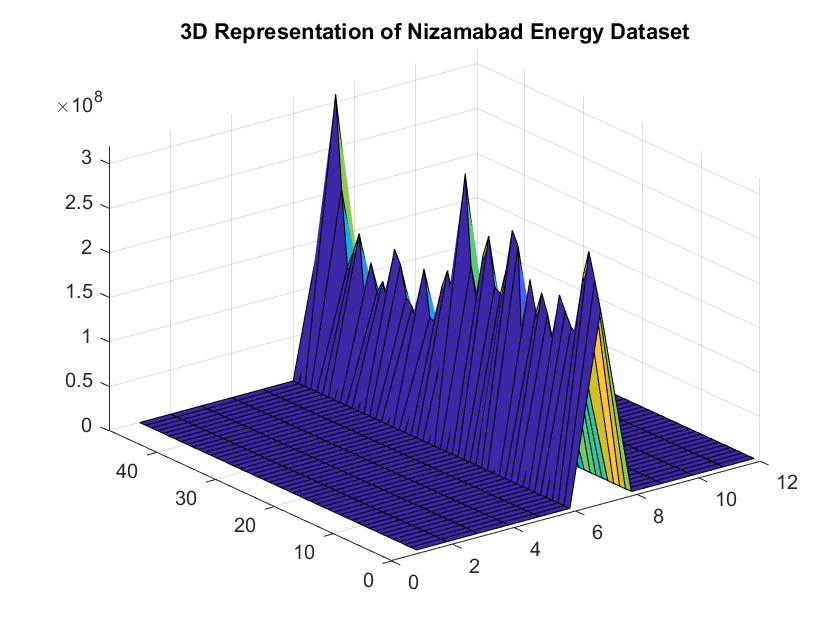

figure;
surf(Energy_Nizamabad);
title('3D Representation of Nizamabad Energy Dataset');

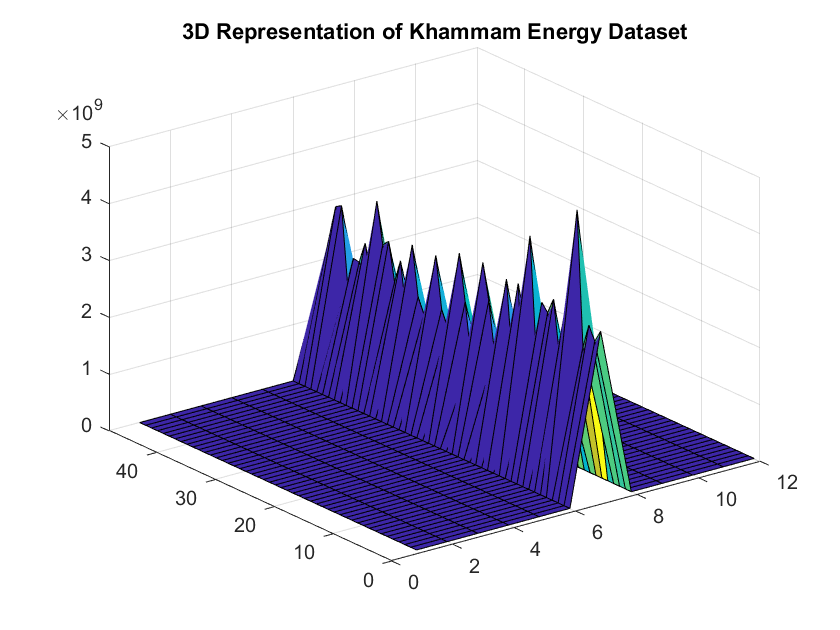

figure;
surf(Energy_Khammam);
title('3D Representation of Khammam Energy Dataset');

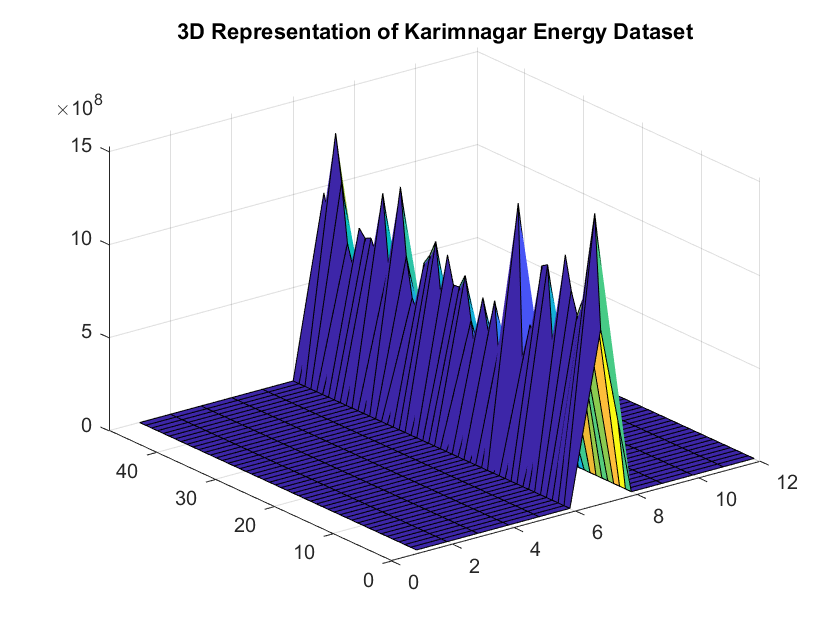

figure;
surf(Energy_Karimnagar);
title('3D Representation of Karimnagar Energy Dataset');


%Saving as .mat files.
save('Energy.mat','Energy_Warangal','Energy_Nizamabad','Energy_Khammam','Energy_Karimnagar');

clear;
clc;

%Loading the Energy values.
load('Energy.mat');

%Available Data.
Y=829:876;

%Months.
M=1:876;

%Interpolation of Energy Values.
%Interpolation using FFT Method is performed to fit the oscillating Data.
%This interpolation is the best option available and provides the least
%deviation from available data.
Energy_Warangal_interpolated= interpft(Energy_Warangal,876);
Energy_Nizamabad_interpolated= interpft(Energy_Nizamabad,876);
Energy_Khammam_interpolated= interpft(Energy_Khammam,876);
Energy_Karimnagar_interpolated= interpft(Energy_Karimnagar,876);

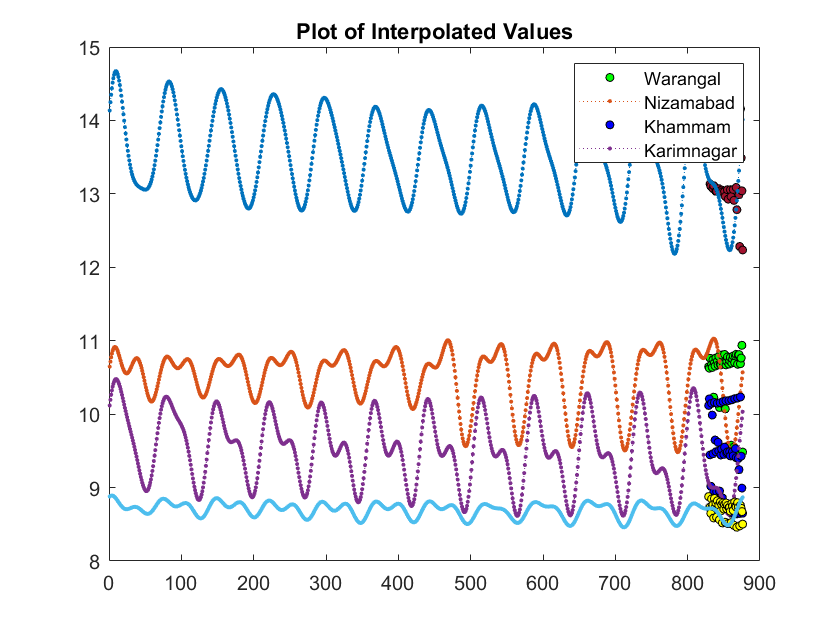

%Plotting the graphs.
for i=1:12
    figure;
h=plot(Y,Energy_Warangal(:,i),'go');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Energy_Warangal_interpolated(:,i),':.');
hold on;
h=plot(Y,Energy_Nizamabad(:,i),'bo');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Energy_Nizamabad_interpolated(:,i),':.');
hold on;
h=plot(Y,Energy_Khammam(:,i),'yo');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Energy_Khammam_interpolated(:,i),':.');
hold on;
h=plot(Y,Energy_Karimnagar(:,i),'o');
set(h,'MarkerFaceColor',get(h,'Color'),'MarkerSize',4,'MarkerEdgeColor', 'k');
hold on;
plot(M,Energy_Karimnagar_interpolated(:,i),':.');
hold off;
title('Plot of Interpolated Values');
legend('Warangal','Nizamabad','Khammam','Karimnagar');
end;


%Monthly_Energy_Interpolated_Vector=[Energy_Warangal_interpolated Energy_Nizamabad_interpolated Energy_Khammam_interpolated Energy_Karimnagar_interpolated];

save('Monthly_Energy_Interpolated_Vector.mat','Energy_Warangal_interpolated', 'Energy_Nizamabad_interpolated', 'Energy_Khammam_interpolated', 'Energy_Karimnagar_interpolated');

clear;
clc;

load('Monthly_Energy_Interpolated_Vector.mat');
load('Energy.mat');

%Smoothening the Curves using various Techniques for Warangal, Nizamabad, Khammam and Karimnagar.
%This Smoothening is customized for each city to fit reality. 
% RLOESS is used.
for i=1:12
Warangal_Smoothened_Monthly_Energy_Interpolated_Vector(:,i)=smooth(1:876,Energy_Warangal_interpolated(:,i),0.1,'rloess');
Nizamabad_Smoothened_Monthly_Energy_Interpolated_Vector(:,i)=smooth(1:876,Energy_Nizamabad_interpolated(:,i),0.1,'rloess');
Khammam_Smoothened_Monthly_Energy_Interpolated_Vector(:,i)=smooth(1:876,Energy_Khammam_interpolated(:,i),0.1,'rloess');
Karimnagar_Smoothened_Monthly_Energy_Interpolated_Vector(:,i)=smooth(1:876,Energy_Karimnagar_interpolated(:,i),0.1,'rloess');
end

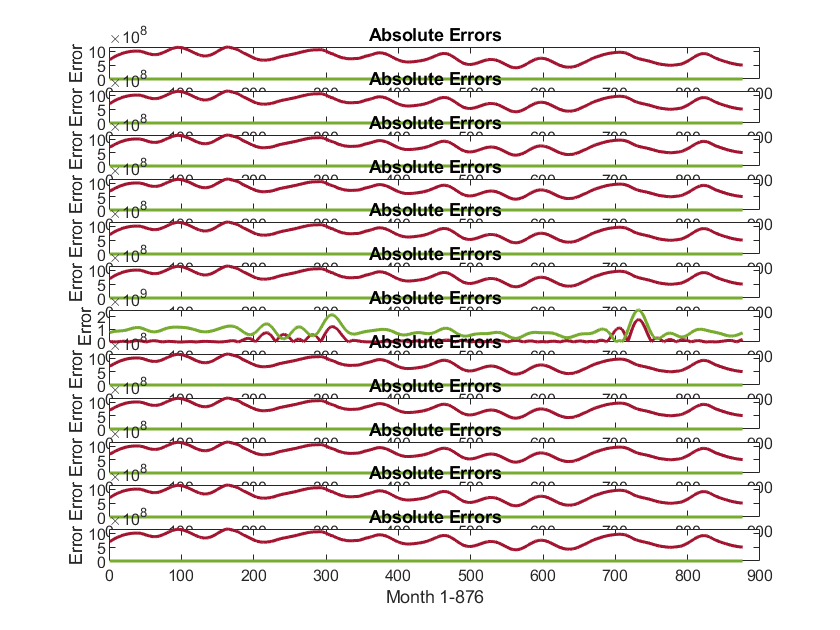

%Checking the absolute errors.
figure;
for i=1:12
subplot(12,1,i);
plot(1:876,abs(Warangal_Smoothened_Monthly_Energy_Interpolated_Vector-Energy_Warangal_interpolated(:,i)),'LineWidth',1.5);
title('Absolute Errors');
xlabel('Month 1-876');
ylabel('Error');
end


Smoothened_Monthly_Energy_Interpolated_Vector=[Warangal_Smoothened_Monthly_Energy_Interpolated_Vector;Nizamabad_Smoothened_Monthly_Energy_Interpolated_Vector;Khammam_Smoothened_Monthly_Energy_Interpolated_Vector;Karimnagar_Smoothened_Monthly_Energy_Interpolated_Vector];

save('Smoothened_Monthly_Energy_Interpolated_Vector.mat','Smoothened_Monthly_Energy_Interpolated_Vector');

clear;
clc;

%Pollution Dataset.
%The values of SO2, NOx, PM10, NH3 are used from this dataset.

%Warangal.
%SO2
Warangal_SO2=[7.0	7.0	7.1	7.0	8.0	7.0	7.0	7.0	7.0	7.0	6.0	8.0 8.0	8.0	8.0	8.0	8.0	7.1	6.0	6.0	6.0	9.0	7.0	7.2 7.0	7.0	7.1	8.2	8.5	8.7	36.1	8.6	8.6	9.1	9.6	9.5 10.3	10.1	10.2	10.1 9.5	8.6	8.5	8.4	7.9	7.4	7.1	6.6 6.0	6.2	5.9	6.0	6.8	7.1	8.6	7.0	7.2	7.2	6.8	7.4 6.4	6.9	7.7	8.9	8.5	8.0	5.8	6.8	7.3	8.1	8.3	7.3 7.1	8.4	8.0	7.6	7.8	7.5	7.2	6.5	7.1	7.9	7.6	8.3];
mean_value=(mean(Warangal_SO2));
Warangal_SO2(Warangal_SO2 == 0) = mean_value;

%NOx
Warangal_NOx=[26.0	19.0	21.8	20.0	19.0	22.0	20.0	28.0	20.0	22.0	22.0	30.0 25.0	27.0	27.0	28.0	27.0	23.6	26.0	22.0	20.0	24.0	27.0	27.3 28.5	39.1	32.0	36.3	41.2	38.2	38.8	35.7	38.0	38.6	46.7	42.1 54.5	56.0	54.6	54.0	55.2	47.6	45.8	47.3	46.9	48.4	50.9	50.5 49.2	51.1	38.1	38.0	39.3	32.2	44.9	45.0	40.7	38.1	53.5	35.2 42.2	47.4	36.3	34.0	32.0	30.8	28.7	32.7	31.2	32.5	34.3	31.0 31.8	31.0	33.1	34.2	34.2	34.7	30.2	26.6	29.9	32.2	35.0	32.6];
mean_value=round(mean(Warangal_NOx));
Warangal_NOx(Warangal_NOx == 0) = mean_value;

%PM10
Warangal_PM10=[76	72	63	73	84	68	56	36	52	61	83	84 76	79	71	72	68	61	41	58	54	62	76	78 97	98	80	82	81	84	70	73	80	89	96	88 91	91	92	89	93	86	87	80	73	85	91	87 89	88	74	26	58	56	48	49	39	54	93	93 81	88	75	71	45	83	57	60	55	64	65	69 73	73	76	60	77	85	47	56	48	63	95	95];
mean_value=round(mean(Warangal_PM10));
Warangal_PM10(Warangal_PM10 == 0) = mean_value;

%NH3
Warangal_NH3=[22	21	24	21	21	28	24	22	20	22	21	23 22	25	22	28	27	21	23	21	21	37	23	23 26	59	58	45	53	61	57	58	52	57	52	58 68	69	68	70	70	69	57	67	61	60	63	66 64	70	54	20	30	34	31	33	31	33	63	36 71	69	41	49	45	43	46	42	44	45	37	37 36	49	39	40	40	39	36	23	27	39	37	35];
mean_value=round(mean(Warangal_NH3));
Warangal_NH3(Warangal_NH3 == 0) = mean_value;

%Make a Single Vector.
Warangal_Pollutants=[Warangal_SO2' Warangal_NOx' Warangal_PM10' Warangal_NH3'];

%Nizamabad.
%SO2
Nizamabad_SO2=[0	0	0	0	0	4.0	4.0	5.0	5.0	6.0	5.0	5.0 5.0	5.0	5.0	5.0	5.0	5.0	5.0	5.0	5.0	6.0	6.0	6.0 6.0	6.0	5.9	5.9	5.9	5.9	5.7	5.6	5.8	6.2	5.6	5.7 5.5	5.6	5.6	5.6	5.5	5.7	5.4	4.8	4.4	4.8	4.6	5.4 5.5	5.5	0	0	0	4.9	5.2	4.7	5.4	5.2	6.1	6.0 5.8	5.1	5.7	5.3	6.0	0	5.7	5.3	5.0	6.2	6.4	5.8 6.9	7.5	6.6	7.8	7.3	6.0	5.5	6.7	7.9	8.6	6.8	7.5];
mean_value=(mean(Nizamabad_SO2));
Nizamabad_SO2(Nizamabad_SO2 == 0) = mean_value;

%NOx
Nizamabad_NOx=[0	0	0	0	0	15.0	17.0	18.0	18.0	22.0	21.0	21.0 20.0	20.0	21.0	20.0	20.0	20.0	21.0	21.0	21.0	21.0	21.0	22.0 22.4	22.4	22.2	21.8	22.6	22.3	22.5	22.4	23.1	23.6	25.0	24.6 24.3	24.9	24.4	23.4	25.0	26.0	25.6	24.4	23.5	25.2	24.7	25.9 27.3	26.6	0	0	0	24.1	25.8	22.2	24.8	24.7	25.9	26.4 24.7	23.4	24.8	25.1	26.0	0	24.8	22.4	23.1	27.3	26.7	25.5 25.5	27.5	26.1	24.0	24.6	23.4	21.3 23.3	25.0	27.4	25.0	22.6];
mean_value=round(mean(Nizamabad_NOx));
Nizamabad_NOx(Nizamabad_NOx == 0) = mean_value;

%PM10
Nizamabad_PM10=[67	64	66	68	71	61	57	58	56	64	60	62 61	62	63	67	68	63	57	59	60	59	59	59 61	61	66	70	47	64	59	60	64	48	56	62 64	61	61	62	64	64	64	65	61	64	62	63 60	60	0	0	0	52	63	60	60	62	62	71 68	67	66	67	60	0	54	45	43	59	66	57 56	59	64	58	56	52	46	52	51	61	56	60];
mean_value=round(mean(Nizamabad_PM10));
Nizamabad_PM10(Nizamabad_PM10 == 0) = mean_value;

%NH3
Nizamabad_NH3=[0	0	0	0	0	21	21	21	21	21	21	21 21	21	21	21	21	17	17	17	17	17	17	18 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 10	10	0	0	0	10	10	10	10	10	10	10 15	20	20	19	17	0	16	15	16	17	17	14 14	15	17	16	14	15	13	14	16	18	16	17];
mean_value=round(mean(Nizamabad_NH3));
Nizamabad_NH3(Nizamabad_NH3 == 0) = mean_value;

%Make a Single Vector.
Nizamabad_Pollutants=[Nizamabad_SO2' Nizamabad_NOx' Nizamabad_PM10' Nizamabad_NH3'];

%Khammam.
%SO2
Khammam_SO2=[6.0 7.0	6.1	8.0	7.0	5.0	8.0	5.0	8.0	7.0	7.0	8.0 7.0	8.0	8.0	8.0	8.0	7.4	7.0	6.0	7.0	7.0	7.0	7.7 8.1	0	7.2	8.6	8.5	8.8	8.6	8.7	8.9	9.1	9.7	9.6 10.6	9.2	10.2	9.9	8.7	8.6	8.1	8.4	8.0	7.1	6.9	6.6 6.0	6.4	6.1	6.0	6.5	8.3	7.9	8.0	7.1	7.4	6.3	7.4 6.8	6.8	7.7	7.9	0	8.4	5.5	6.0	9.2	7.4	7.5	7.0 6.8	7.6	7.8	7.3	7.1	7.4	7.4	7.4	7.0	7.4	8.0	7.1];
mean_value=(mean(Khammam_SO2));
Khammam_SO2(Khammam_SO2 == 0) = mean_value;


%NOx
Khammam_NOx=[19.0	19.0	20.7	19.0	19.0	21.0	22.0	14.0	17.0	23.0	24.0	27.0 27.0	26.0	28.0	27.0	27.0	24.0	22.0	23.0	22.0	19.0	20.0	26.3 28	38.6	31.6	36.0	40.1	37.9	36.8	36.4	38.7	37.9	44.3	41.8 55.1	57.8	54.6	54.8	53.6	46.9	49.8	48.5	49.7	50.8	52.0	48.9 49.1	49.0	45.0	20.0	47.1	37.2	45.1	26.0	38.6	39.9	49.7	38.6 47.0	38.0	36.2	27.6	0	34.1	35.9	35.9	34.0	31.0	37.6	41.8 29.8	30.7	51.5	44.6	41.0	45.4	45.6	41.5	31.2	30.9	30.0	29.1];
mean_value=round(mean(Khammam_NOx));
Khammam_NOx(Khammam_NOx == 0) = mean_value;

%PM10
Khammam_PM10=[46	51	54	51	47	47	41	37	39	48	55	60 60	64	54	54	57	42	38	64	50	63	54	60 67	66	71	77	77	83	75	79	84	85	92	88 95	90	91	90	88	81	77	84	78	86	85	84 88	84	83	80	54	43	43	33	37	49	82	98 101	84	65	54	0	90	69	67	85	61	86	78 80	78	76	78	77	81	73	56	41	57	78	112];
mean_value=round(mean(Khammam_PM10));
Khammam_PM10(Khammam_PM10 == 0) = mean_value;


%NH3
Khammam_NH3=[0	0	0	0	0	20	22	20	21	21	28	22 21	23	27	23	23	23	22	21	19	29	32	26 25	62	55	49	58	57	56	51	54	53	54	63 62	65	67	73	68	64	61	60	64	61	64	68 66	67	65	20	35	45	37	33	40	40	67	41 67	68	43	46	0	38	60	60	48	48	53	55 45	48	65	65	66	67	62	44	38	39	35	33];
mean_value=round(mean(Khammam_NH3));
Khammam_NH3(Khammam_NH3 == 0) = mean_value;

%Make a Single Vector.
Khammam_Pollutants=[Khammam_SO2' Khammam_NOx' Khammam_PM10' Khammam_NH3'];

%Karimnagar.
%SO2
Karimnagar_SO2=[8.0	9.0	7.7	7.0	5.0	5.0	4.0	6.0	6.0	6.0	7.0	7.0 7.0	7.0	8.0	8.0	7.0	6.6	7.0	6.0	7.0	8.0	7.0	7.7 7.9	6.5	7.4	8.7	8.8	9.1	8.7	7.6	9.1	9.0	9.5	9.3 10.7	10.7	10.4	10.4	10.2	9.1	9.1	8.5	8.0	7.4	7.1	6.8 5.9	6.5	5.7	7.2	7.1	7.5	8.8	8.0	7.0	7.2	7.4	8.9 7.1	7.1	8.2	8.2	8.3	7.9	6.6	6.9	6.7	7.2	6.8	7.9 7.8	6.4	6.8	8.0	6.3	6.4	7.0	6.0	6.7	6.7	6.2	6.2];
mean_value=(mean(Karimnagar_SO2));
Karimnagar_SO2(Karimnagar_SO2 == 0) = mean_value;

%NOx
Karimnagar_NOx=[22.0	25.0	32.1	29.0	21.0	19.0	20.0	20.0	23.0	23.0	23.0	26.0 25.0	31.0	26.0	26.0	27.0	22.0	27.0	26.0	22.0	32.0	22.0	26.7 38.5	45.8	36.3	40.0	41.9	39.0	33.6	38.9	40.2	34.0	44.2	40.2 54.4	58.4	57.8	61.2	58.9	50.5	47.8	51.8	51.2	50.1	52.4	56.2 52.5	56.3	49.3	38.0	45.2	37.1	48.1	43.0	43.3	38.9	64.8	45.6 56.6	47.0	41.7	40.7	42.4	39.7	32.4	32.4	34.7	35.3	34.2	30.9 30.3	27.9	26.7	28.4	26.8	32.0	29.3	27.4	29.9	30.6	26.1	32.7];
mean_value=round(mean(Karimnagar_NOx));
Karimnagar_NOx(Karimnagar_NOx == 0) = mean_value;

%PM10
Karimnagar_PM10=[69	59	42	62	52	47	23	33	29	50	69	83 84	75	86	79	82	59	51	56	62	69	91	90 117	88	89	102	100	101	89	91	101	98	110	100 107	103	105	113	105	100	100	102	97	104	107	119 116	121	115	33	72	55	124	70	99	156	120	114 114	116	65	72	68	69	57	64	66	68	73	83 82	92	99	70	78	92	69	55	58	62	103	139];
mean_value=round(mean(Karimnagar_PM10));
Karimnagar_PM10(Karimnagar_PM10 == 0) = mean_value;

%NH3
Karimnagar_NH3=[27	24	25	21	23	21	23	21	21	25	22	24 25	26	24	25	24	23	22	25	21	39	26	26 25	54	62	53	60	61	59	66	53	56	54	56 62	64	70	75	71	69	63	74	64	66	69	73 67	75	65	20	33	36	34	37	38	38	75	48 72	72	46	45	42	40	26	22	28	25	26	32 32	22	23	24	20	31	33	19	20	29	22	35];
mean_value=round(mean(Karimnagar_NH3));
Karimnagar_NH3(Karimnagar_NH3 == 0) = mean_value;

%Make a Single Vector.
Karimnagar_Pollutants=[Karimnagar_SO2' Karimnagar_NOx' Karimnagar_PM10' Karimnagar_NH3'];

%Interpolation using FFT Method.
Warangal_Pollution_interpolated= interpft(Warangal_Pollutants,876);
Nizamabad_Pollution_interpolated= interpft(Nizamabad_Pollutants,876);
Khammam_Pollution_interpolated= interpft(Khammam_Pollutants,876);
Karimnagar_Pollution_interpolated= interpft(Karimnagar_Pollutants,876);

%Making the Final Vector.
Pollutants_Concentration_Vector=[Warangal_Pollution_interpolated; Nizamabad_Pollution_interpolated; Khammam_Pollution_interpolated; Karimnagar_Pollution_interpolated];

%Saving in .mat format.
save('Pollutants_Concentration_Vector.mat','Pollutants_Concentration_Vector');

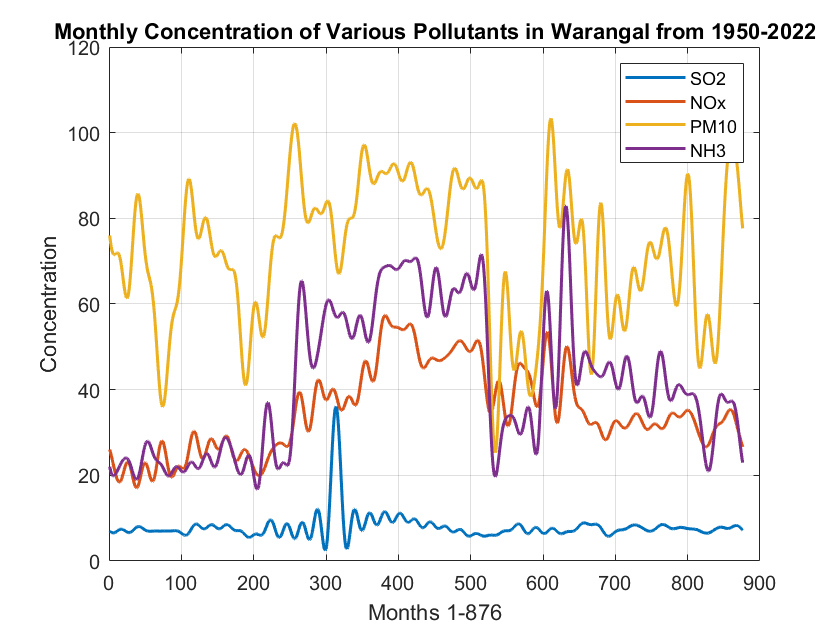

%Plotting the graphs of the Interpolated values.
figure;
for i=1:4
plot(1:876,Warangal_Pollution_interpolated(:,i),'LineWidth',1.5);
hold on;
end
hold off;
grid on;
legend('SO2','NOx','PM10','NH3');
xlabel('Months 1-876');
ylabel('Concentration');
title('Monthly Concentration of Various Pollutants in Warangal from 1950-2022');

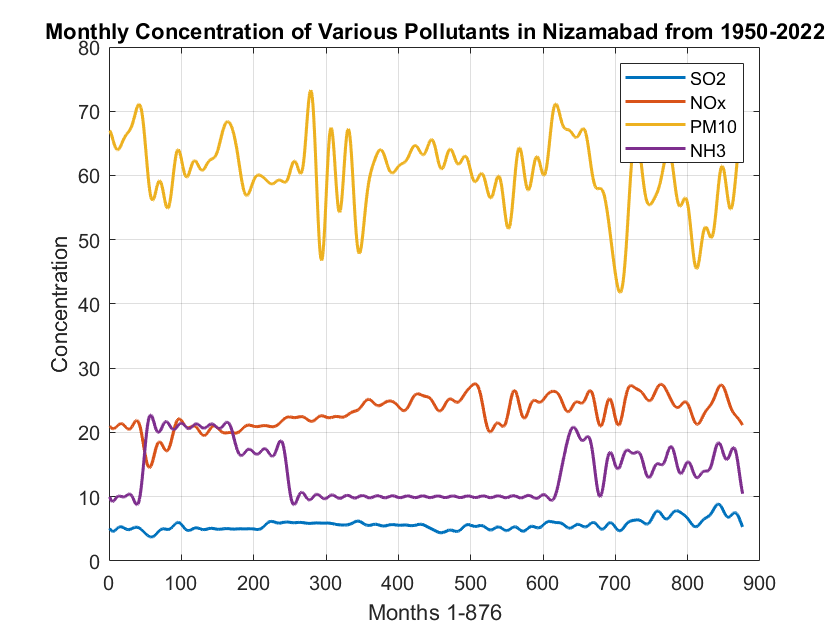


figure;
for i=1:4
plot(1:876,Nizamabad_Pollution_interpolated(:,i),'LineWidth',1.5);
hold on;
end
hold off;
grid on;
legend('SO2','NOx','PM10','NH3');
xlabel('Months 1-876');
ylabel('Concentration');
title('Monthly Concentration of Various Pollutants in Nizamabad from 1950-2022');

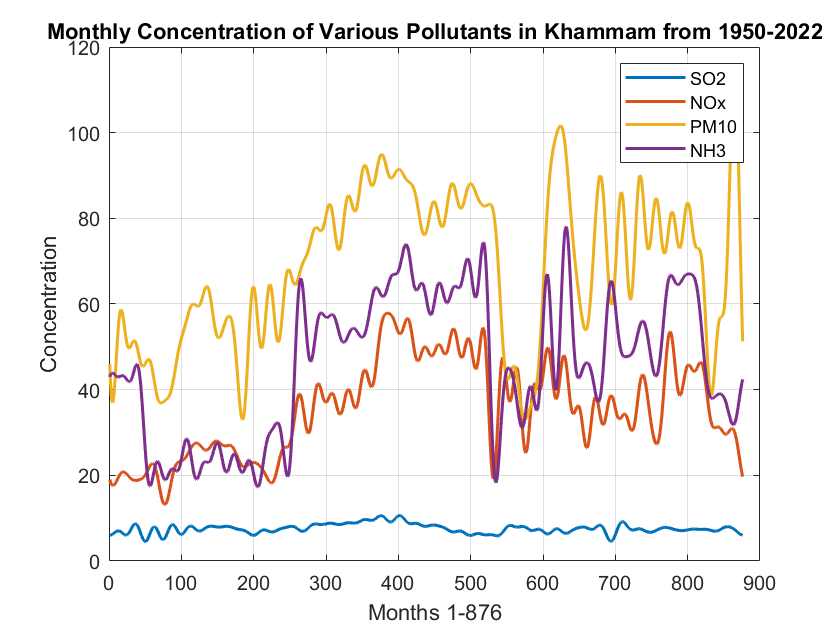


figure;
for i=1:4
plot(1:876,Khammam_Pollution_interpolated(:,i),'LineWidth',1.5);
hold on;
end
hold off;
grid on;
legend('SO2','NOx','PM10','NH3');
xlabel('Months 1-876');
ylabel('Concentration');
title('Monthly Concentration of Various Pollutants in Khammam from 1950-2022');

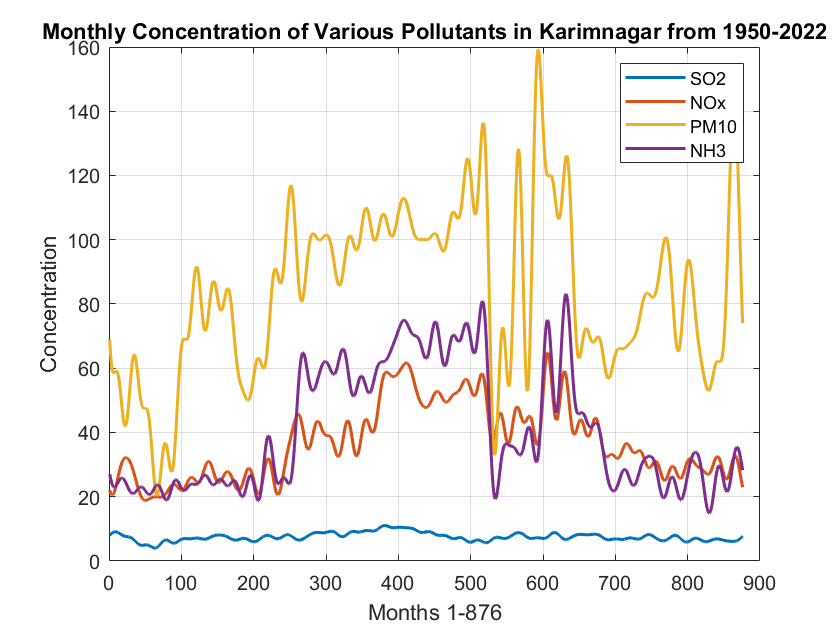


figure;
for i=1:4
plot(1:876,Karimnagar_Pollution_interpolated(:,i),'LineWidth',1.5);
hold on;
end
hold off;
grid on;
legend('SO2','NOx','PM10','NH3');
xlabel('Months 1-876');
ylabel('Concentration');
title('Monthly Concentration of Various Pollutants in Karimnagar from 1950-2022');

clear;
clc;

%Interpolating the existing MERRA-2 Dataset.

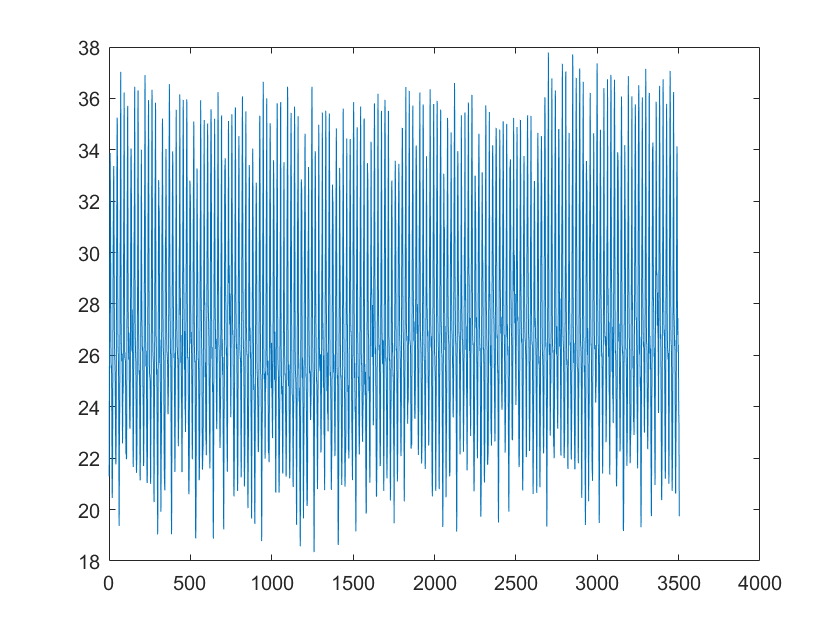

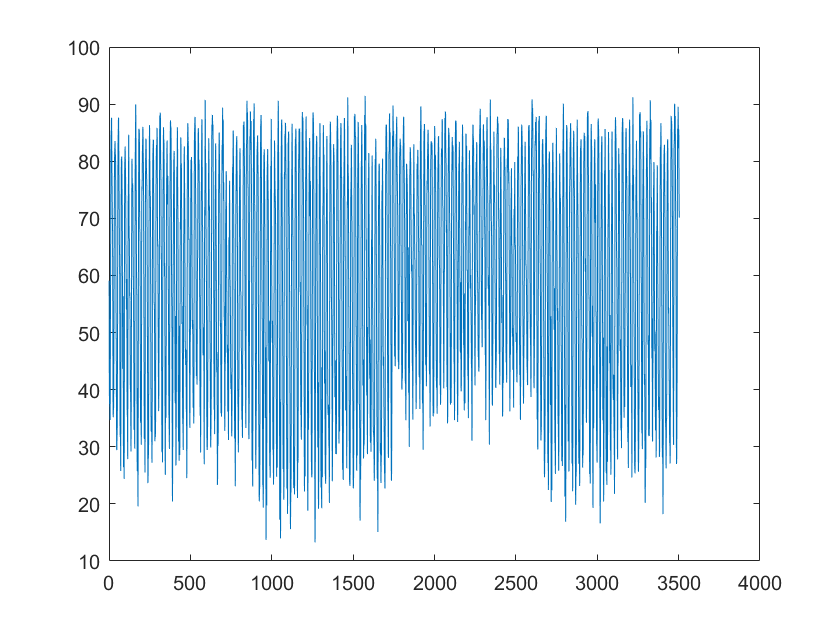

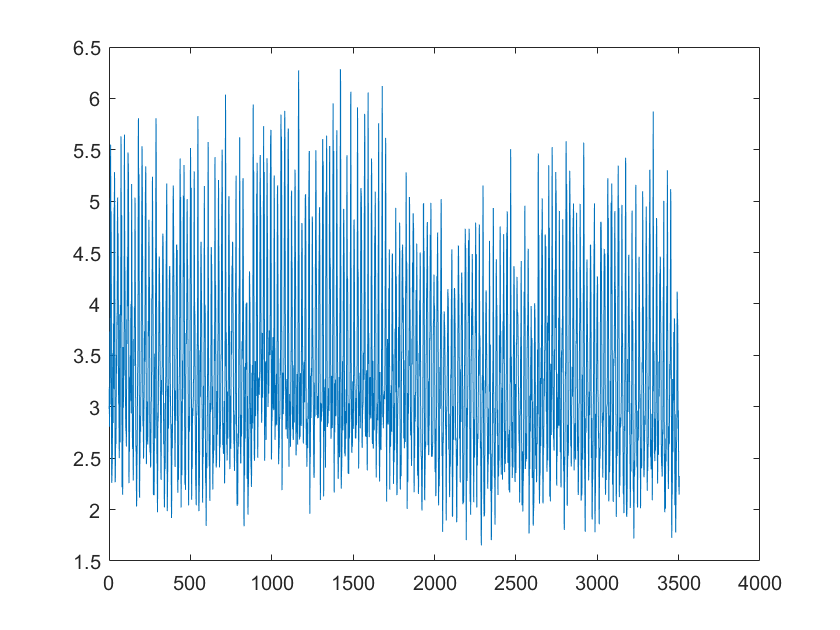

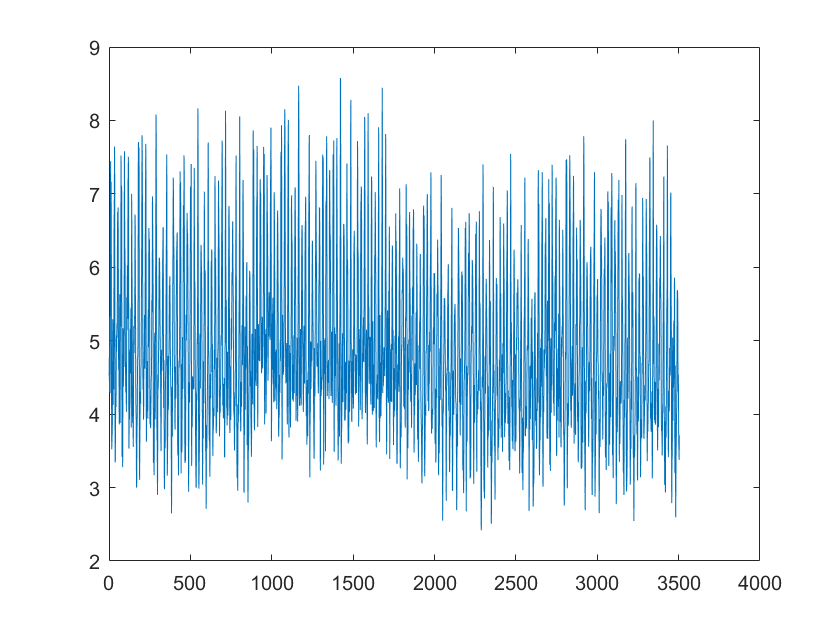

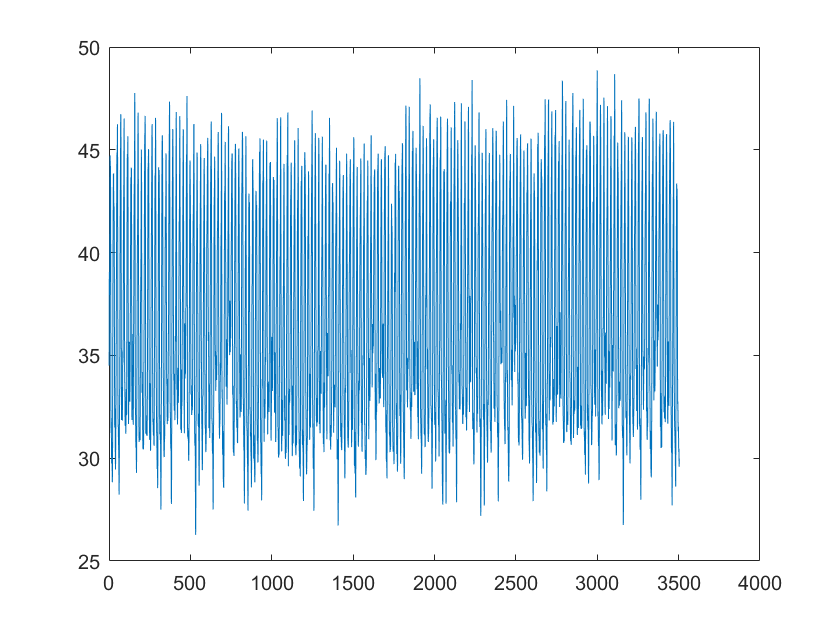

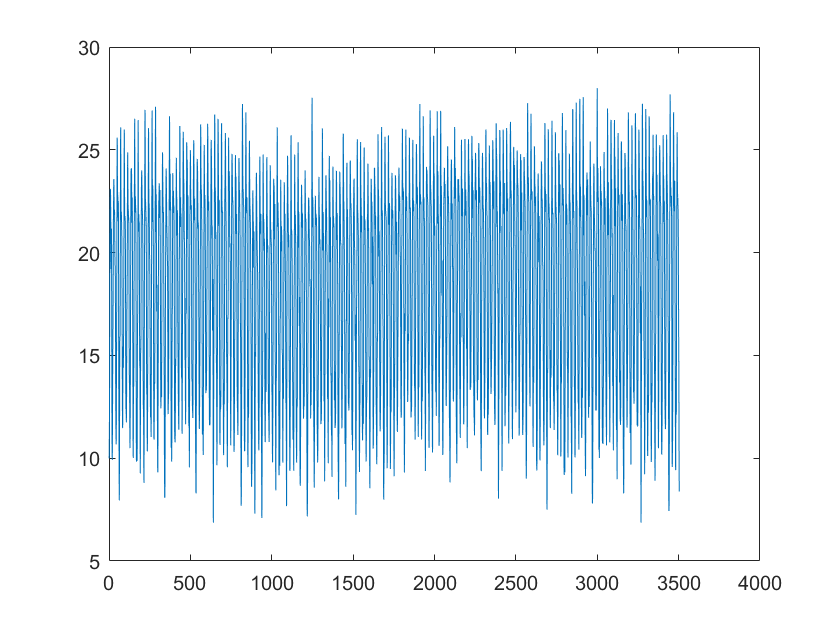

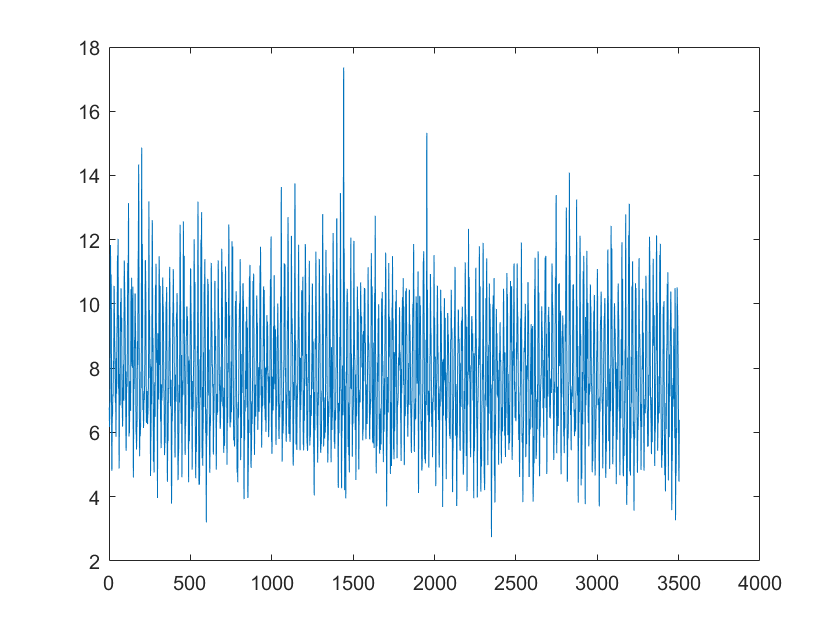

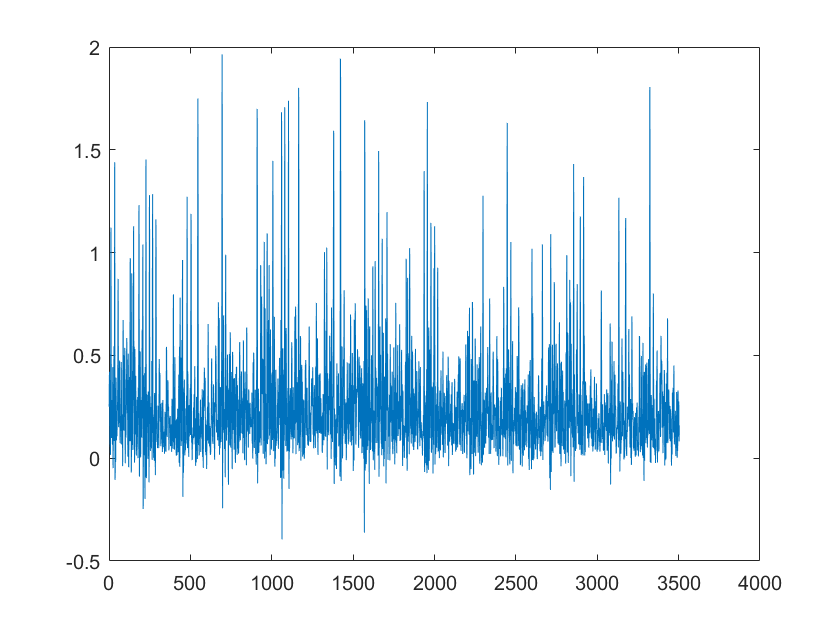

% import the CSV file as a table
my_table = readtable('MERRA-2.csv');

% convert the table to a double array
data = table2array(my_table);

%Creating a new array for storing Interpolated data.
MERRA_2_Interpolated=[];

for i=1:492:1968
    x=data(i:i+491,:);
    x_interpolated= interpft(x,876);
    MERRA_2_Interpolated=[MERRA_2_Interpolated; x_interpolated];
end

for i=1:11
MERRA_2_Interpolated_Smoothened(:,i)=smooth(1:3504,MERRA_2_Interpolated(:,i),0.5,'rloess');
end

%Plotting the Interpolated Features.
for i=1:11
    figure;
    plot(1:3504,MERRA_2_Interpolated(:,i));
end

%Preparing the Final "Heatwaves Dataset.csv" file with all features for
%Model Building.
load('Population_Monthly_Interpolated_Vector.mat')

Data=[MERRA_2_Interpolated_Smoothened Population_Monthly_Interpolated_Vector'];
csvwrite('Heatwaves Dataset.csv',Data);

clear;
clc;

%Interpolating the AQI Dataset.

%AQI dataset.
%Warangal Mee-Seva Station.
Warangal_AQI=[76 72	63	73	84	68	63	38	52	61	83	84 76  78  71  72	68	61	48	60	62	62	76	78 94	96	79	83	81	84	70	73	80	89	94	88 91	91	92	89	93	86	87	80	73	85	91	87 89	88	74	41	65	58	67	61	55	61	92	91 81	88	75	71	51	81	57	60	55	64	65	69 73	73	76	60	77	85	47	56	48	64	94	94];

%Nizamabad.
Nizamabad_AQI=[69	59	44	62	52	48	32	36	31	56	69	84 61 62 63 67	68	63	57	60	59	61	61	59 61	61	66	70	54	64	59	60	64	48	60  62 64	61	61	62	64	69	72	71	61	69	62	66 64	64	66	38	50	52	63	60	62	62	63	81 69	68	66	69	41	0	54	45	43	59	66	57 56	59	64	58	56	54	46	53	54	63	56	59];
mean_value=round(mean(Nizamabad_AQI));
Nizamabad_AQI(Nizamabad_AQI == 0) = mean_value;

%Khammam.
Khammam_AQI=[69	59	44	62	52	48	32	36	31	56	69	84 84  75  86  79	82	59	55	55	62	71	91	90 64	68	71	77	77	83	75	79	84	85	92	88 94	90	91	90	88	81	77	84	78	86	85	84 88	84	83	80	63	48	70	37	52	62	83	95 100	84	68	54	0	88	69	67	85	61	86	78 80	78	77	79	77	81	73	58	42	57	78	115];
mean_value=round(mean(Khammam_AQI));
Khammam_AQI(Khammam_AQI == 0) = mean_value;

%Karimnagar.
Karimnagar_AQI=[47	51	54	51	47	47	41	37	39	48	55	60 60 64	54	55	57	42	41	53	50	63	54	60 111	87	89	100	100	100	89	91	100	98	106	100 104	102	103	109	103	99	100	99	97	102	105	112 111	114	110	39	72	58	114	70	96	137	114	108 110	110	69	73	68	72	57	64	66	68	73	82 82	90	96	70	76	89	69	55	58	63	101	126];

AQI_Vector_Actual=[Warangal_AQI Nizamabad_AQI Khammam_AQI Karimnagar_AQI];

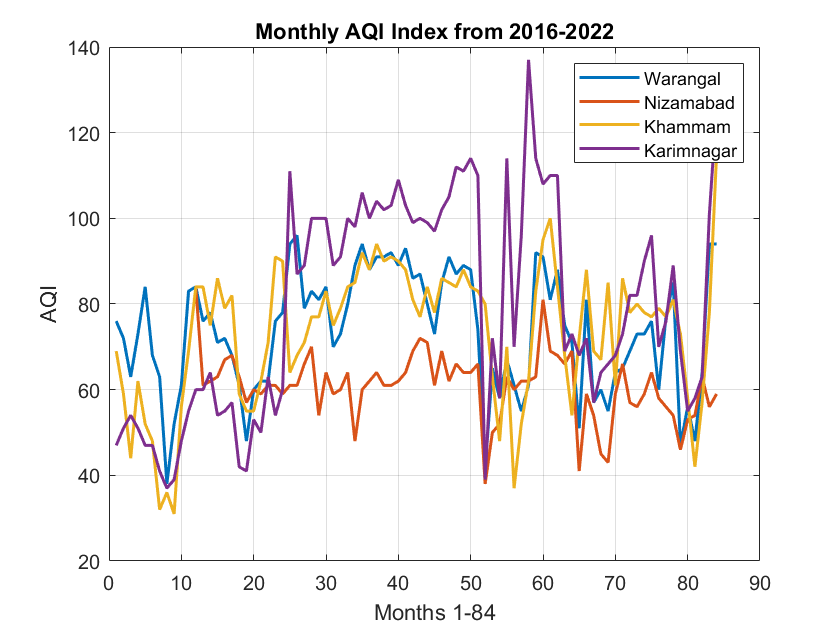

%Plotting the AQI Index.
figure;
plot(1:84,Warangal_AQI,'LineWidth',1.5);
hold on;
plot(1:84,Nizamabad_AQI,'LineWidth',1.5);
hold on;
plot(1:84,Khammam_AQI,'LineWidth',1.5);
hold on;
plot(1:84,Karimnagar_AQI,'LineWidth',1.5);
hold off;
grid on;
title('Monthly AQI Index from 2016-2022');
xlabel('Months 1-84');
ylabel('AQI');
legend('Warangal','Nizamabad','Khammam','Karimnagar');

%Interpolation.
AQI_Warangal_interpolated= interpft(Warangal_AQI,876);
AQI_Nizamabad_interpolated= interpft(Nizamabad_AQI,876);
AQI_Khammam_interpolated= interpft(Khammam_AQI,876);
AQI_Karimnagar_interpolated= interpft(Karimnagar_AQI,876);

%Single Vector.
AQI_Vector_Interpolated=[AQI_Warangal_interpolated AQI_Nizamabad_interpolated AQI_Khammam_interpolated AQI_Karimnagar_interpolated];

%Saving in .mat format.
save('AQI_Vector.mat','AQI_Vector_Actual','AQI_Vector_Interpolated');

clear;
clc;

%Making the Final "AQI.csv" file with all the Features for Model Building.
load('AQI_Vector.mat');
load('Population_Monthly_Interpolated_Vector.mat');
load('Smoothened_Monthly_Energy_Interpolated_Vector.mat');
load('Pollutants_Concentration_Vector.mat');

Data=[Population_Monthly_Interpolated_Vector' Smoothened_Monthly_Energy_Interpolated_Vector round(AQI_Vector_Interpolated)'];

save('Dataset.mat','Data');
csvwrite('AQI.csv',Data);